# 超导能隙方程

P. Coleman的方程

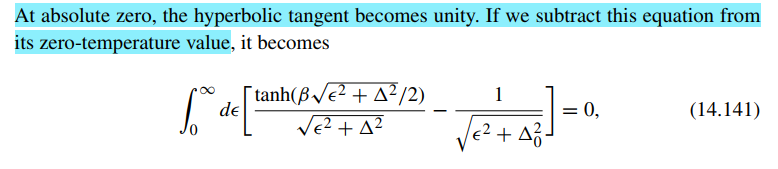

理论应当可以求解得到

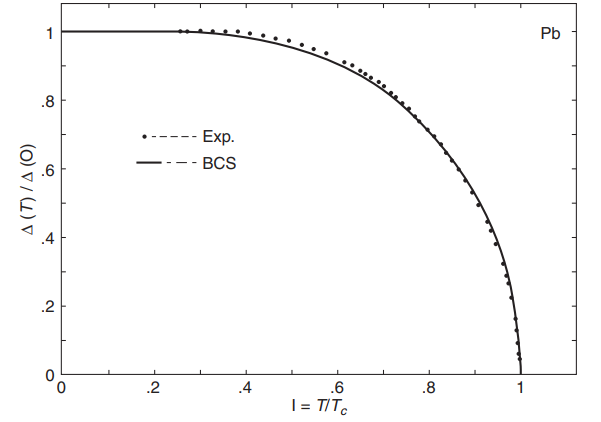

param.t = 1;
param.nc = 0.5;
param.T = 0.1 * param.t;
param.t1 = 0;
param.t2 = 0;
param.g = 2.0 * t;
param.mu = 0;
param.Delta = 2;

% 第一个初值为能隙，第二个初值为温度
% x0 = [param.Delta, 0];
Tem = linspace(0,1,101);
x0 = [param.Delta];
Delta = zeros(size(Tem));
for ii = 1: length(Tem)
    param.T = Tem(ii);
    Fun = @(x)SC_Gap(x, param);
    Delta(ii) = fsolve(Fun, x0);
end


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>



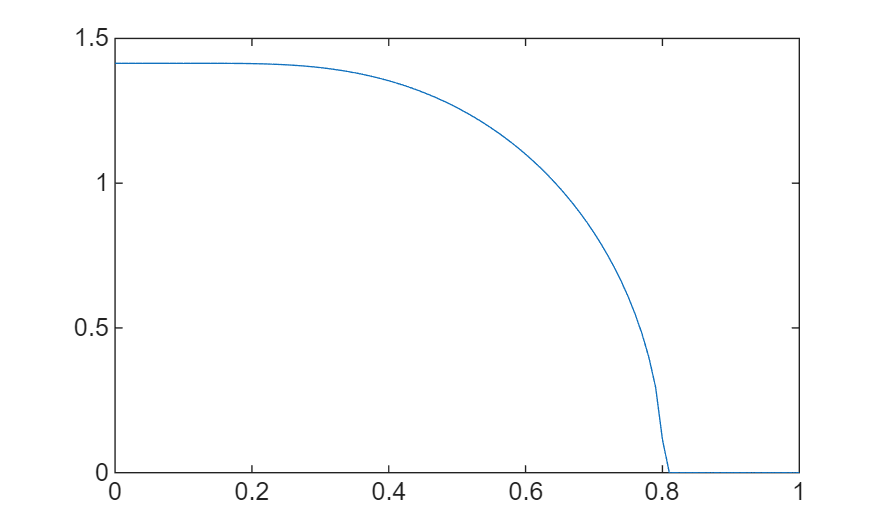

plot(Tem, Delta)


disp(['找到超导零温能隙与临界温度的比值为: ',num2str(2*Delta(1)./Tem(find(abs(Delta)<1e-2,1)))])

找到超导零温能隙与临界温度的比值为: 3.4919


disp(['理论预期为','3.53'])

理论预期为3.53


对应的函数为

function [y] = SC_Gap(Var, param)

dd = 1e-6;

    function [z1] = Gap_eq(epsilon)
        E_k = sqrt(epsilon.^2 + Var(1)^2+dd);
        % E_k = \sqrt{xi_k^2 + \Delta^2}
        % z1 = tanh(E_k/(2*Var(2)))./(E_k)-1./(sqrt(epsilon.^2 + param.Delta));
        z1 = tanh(E_k/(2*param.T))./(E_k)-1./(sqrt(epsilon.^2 + param.Delta));
    end

Sp1 = integral(@Gap_eq, 0, Inf);

y = Sp1;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [y] = gamma(kx,ky)
%y=cos(kx)-cos(ky); % dx^2-y^2-wave:cos(kx)-cos(ky).   
y=1;               % Uniform s-wave:1.  
%y=cos(kx)+cos(ky); % Extended s-wave:cos(kx)+cos(ky).
%y=sin(kx).*sin(ky);% dxy-wave:sin(kx)*sin(ky).
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%